3a-c

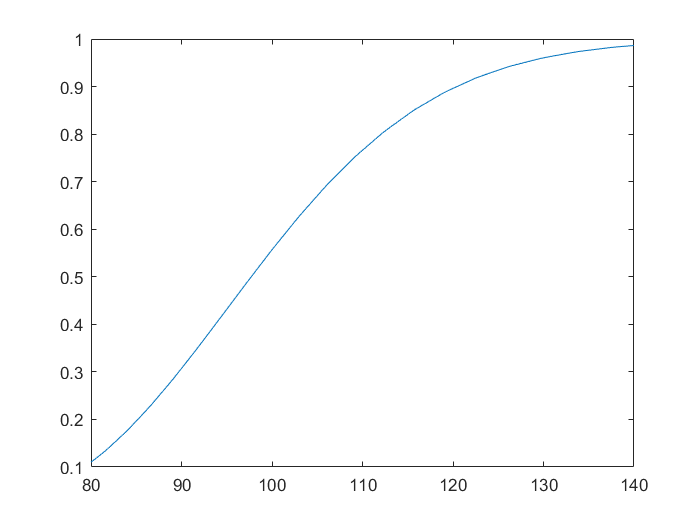

S0=100;
r=0.02;
sigma=0.23;
T=1;
N=250;
m=1;
K=100;

[~,s,delta]=binomialDeltaPowerCall(S0,r,sigma,T,N,m,K);

stocknew=linspace(80,140,100);

y=interpDelta(delta(1:N/2,N/2), s(1:N/2,N/2), stocknew);
plot(stocknew, y)


% since we are at T/2, there is T/2 time left till options expires
bls=blsdelta(stocknew,K,r,T/2,sigma)

bls =     0.1095    0.1184    0.1278    0.1376    0.1479    0.1585    0.1696    0.1810    0.1928    0.2051    0.2176    0.2305    0.2438    0.2573    0.2711    0.2852    0.2995    0.3141    0.3288    0.3437    0.3588    0.3739    0.3892    0.4045    0.4199    0.4353    0.4508    0.4661    0.4815    0.4968    0.5120    0.5270    0.5420    0.5568    0.5714    0.5859    0.6001    0.6141    0.6279    0.6415    0.6548    0.6678    0.6806    0.6931    0.7053    0.7172    0.7288    0.7401    0.7511    0.7617


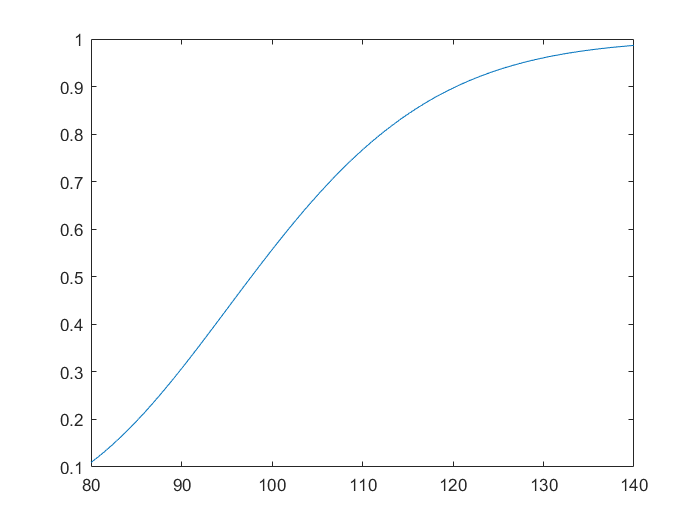

plot(stocknew, bls)

we observe delta (corresponding to the stock prices) computed using our binomial lattice is almost exactly the same with delta calculate from blsprice()

3d

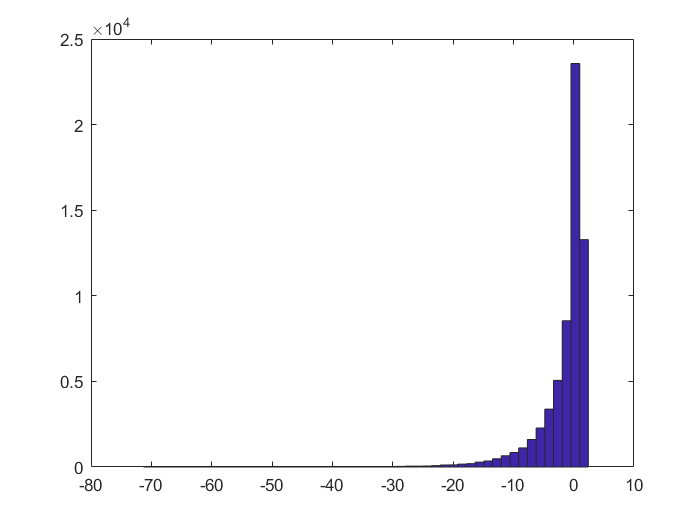

N=250;
dt = T/N;
% number of simulation is O((1/dt)^2)
M=N^2;
m=2;
mu=0.18;
beta = 0.05;
[v,s,delta]=binomialDeltaPowerCall(S0,r,sigma,T,N,m,K);

% data for drawing table
tabvar = zeros(5,1);
tabcvar = zeros(5,1);

% no hedging

% at beginning, we sell option, and hold bond=val(C0)
bond0 = v;
S=ones(M,1).*s(1,1);
for tstep = 1:N 
    S=S + mu*dt*S + normrnd(0,1,M,1).*sqrt(dt).*sigma.*S;
end 
netvaluef = bond0*exp(T*r) - max(S-K , 0).^m;
pandl = exp(-r*T).*netvaluef./v;
drawPandL(pandl)

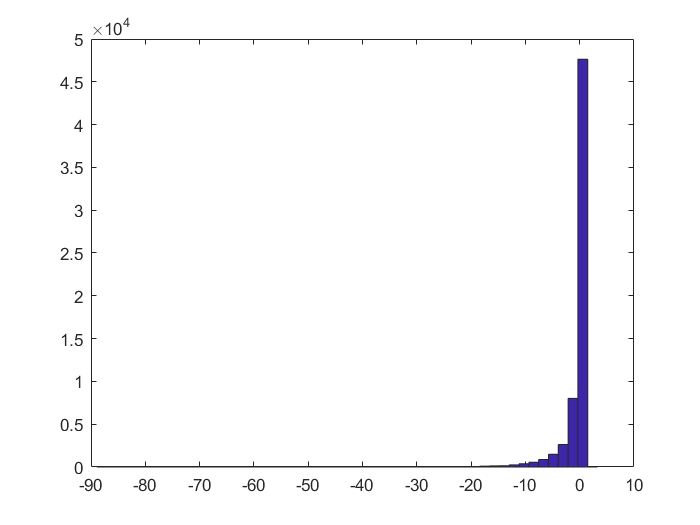

[tabvar(1,1),tabcvar(1,1)]=dVaRCVaR(pandl, beta);


% hedge once 
% setting hedging freqency to once every N+2 time just means never hedge
% because we only have N timesteps
netvaluef=dynamichedging(v,s,delta, mu, sigma, T, N, M, N+2,K,m,r);
pandl = exp(-r*T).*netvaluef./v;
drawPandL(pandl)

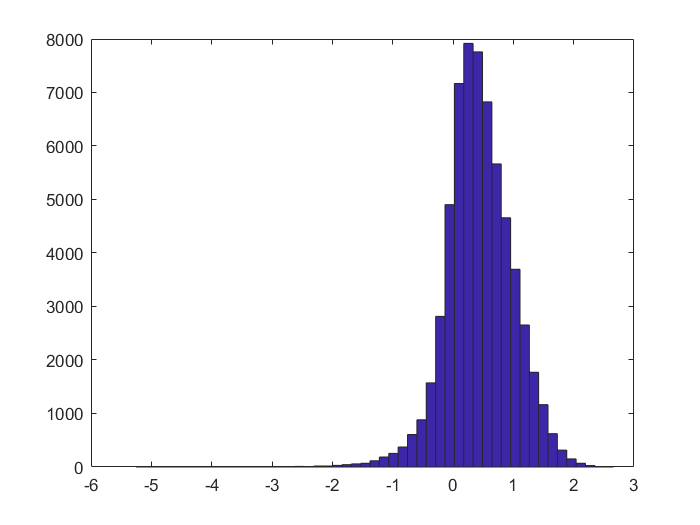

[tabvar(2,1),tabcvar(2,1)]=dVaRCVaR(pandl, beta);


% hedge every month (once every 20 timesteps)
netvaluef=dynamichedging(v,s,delta, mu, sigma, T, N, M, 20,K,m,r);
pandl = exp(-r*T).*netvaluef./v;
drawPandL(pandl)

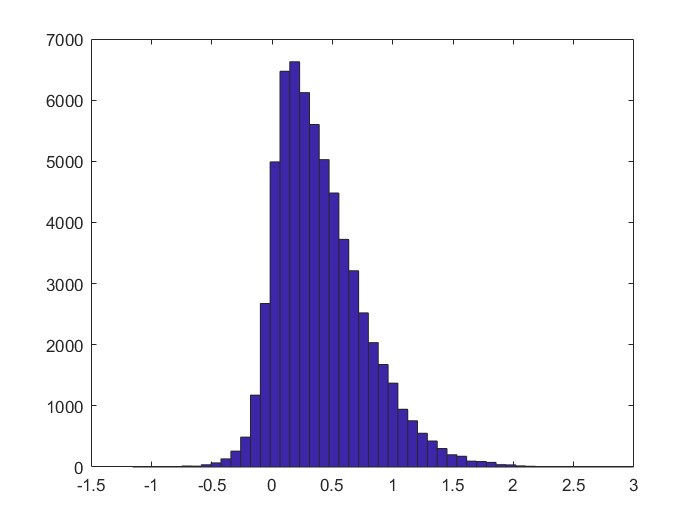

[tabvar(3,1),tabcvar(3,1)]=dVaRCVaR(pandl, beta);


% hedge every week (once every 5 timesteps)
netvaluef=dynamichedging(v,s,delta, mu, sigma, T, N, M, 5,K,m,r);
pandl = exp(-r*T).*netvaluef./v;
drawPandL(pandl)

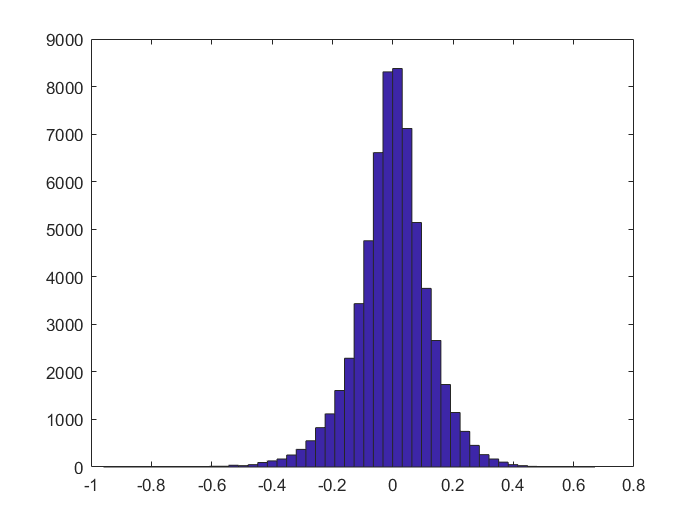

[tabvar(4,1),tabcvar(4,1)]=dVaRCVaR(pandl, beta);

% hedge every day 
netvaluef=dynamichedging(v,s,delta, mu, sigma, T, N, M, 1,K,m,r);
pandl = exp(-r*T).*netvaluef./v;
drawPandL(pandl)

[tabvar(5,1),tabcvar(5,1)]=dVaRCVaR(pandl, beta);

frequency = {'never';'once';'monthly';'weekly';'everyday'};

table(tabvar, tabcvar, 'RowNames',frequency)

ans = 5×2 table
                 tabvar      tabcvar 
                _________    ________

    never         -9.9973     -16.077
    once          -5.1869     -10.349
    monthly        -0.392    -0.81304
    weekly      -0.061578    -0.17593
    everyday     -0.20704    -0.29467


we observe as we trade more frequently, 

the histogram change from left skewed (meaning a lot of small extreme values) to approximately bell shaped.

the x-axis of histogram becomes smaller, as there are fewer extreme values.

Also, when are not trading frequently, it's more likely to loss money than to have profit.

(e)

as we trade more frequently, the var and cvar increase and goes to zero. 

var and cvar and negative, which is expected as it's the worst case scenario

the speed var and cvar decrease is decreasing as we increase number of hedging

for the first four cases (except hedge everyday), cvar is approcimately twice var

function [V ,S_mat, delta_mat] = binomialDeltaPowerCall(S0, r, sigma, T, N, m, K)
    % S_mat[i,j] indicates the stock price at timestep i, 
    % given stock price went down j times
    % delta_mat[i,j] indicates the amount of stock required at timestep i, 
    % in order to hedge the option, given stock price went down j times.
    dt = T/(N);
    % up and down ratio
    u=exp(sigma*sqrt(dt));
    d=1/u;
    % up probability
    q = (exp(r*dt)-d)/(u-d);
    S_mat = zeros(N+1,N+1);
    delta_mat = zeros(N+1,N+1);
    % stock price at T
    S_mat(1:N+1,N+1) = S0*u.^(N:-1:0).*d.^(0:N);
    % option value at T
    V = max(S_mat(1:N+1,N+1)-K , 0).^m;
    % backward iterations:
    for t = N:-1:1         
        S_mat(1:t,t) = exp(-r*dt)* (S_mat(1:t,t+1)*(q)+S_mat(2:t+1,t+1)*(1-q));
        v_change = V(1:t)-V(2:t+1);
        % we need dV/dS stock to hedge the option
        delta_mat(1:t,t) = v_change./(S_mat(1:t,t+1)-S_mat(2:t+1,t+1));
        V = exp(-r*dt)* (V(1:t)*(q)+V(2:t+1)*(1-q));
    end
end

function [ret] = interpDelta(deltan, Sn, S)
    % add fake value to Sn and deltan, so that for stock price out of
    % bound, we get the value of delta corresponding to the closest Stock
    % price.
    % NOTE: here we assume Sn is increasing! otherwise this function does
    % not work
    Sn=[0;Sn;100^100];
    deltan=[deltan(1,1);deltan;deltan(length(deltan),1)];
    ret=interp1(Sn,deltan,S);
end

function netvaluef = dynamichedging(v,s, delta, mu, sigma, T, N, M, freq,K,m,r)
    % freq means we trade once every freq timesteps
    % we would hedge once at t0 no matter what
    
    %input: s, delta are matrix of stock price and delta hedging from
    %binomial lattice, other inputs are numbers
    
    dt = T/N;
    % stock price at beggining is given
    Si = s(1,1);
    S= ones(M,1)*Si;
    % at t0, we do the hedging, getting our initial delta vector
    deltaold=ones(M,1).* delta(1,1);
    % prepare the bond such that initial profolio value is 0
    bond = ones(M,1).* ( v-delta(1,1)*Si );
    % all bond, deltaold, S are vectors of length M, each indice indicate
    % one simulation.
    
    for tstep = 1:N 
        S=S + mu*dt*S + normrnd(0,1,M,1).*sqrt(dt).*sigma.*S;
        if mod(tstep, freq)==0
            newdelta = interpDelta(delta(1:tstep, tstep), s(1:tstep, tstep), S);
            % bond get interest rate for time dt, then we buy stock {+increase_of_delta*S - bond}
            bond = bond.*exp(r*dt) - (newdelta-deltaold) .* S ;
            deltaold=newdelta;
        end 
    end 
    netvaluef =  bond.*exp(r*dt) - max(S-K , 0).^m + deltaold .* S;
end 

function drawPandL(pandl)
    % convinient function to draw histograms
    minv=(min(pandl));
    maxv=(max(pandl));
    range = minv: (maxv-minv)/50:maxv;
    counts = histc(pandl , range);
    bar(range, counts,'histc')
end

function [var,cvar] = dVaRCVaR(pandl, beta)
    n=length(pandl);
    pandl = sort(pandl);
    var = pandl(round(beta*n));
    cvar = mean(pandl(1:round(beta*n)));    
end

